# Drone Payload Structure Design and Analysis

In this project, you are optimizing drone arm design, including geometry and material selection, to maximize payload capacity while ensuring structural integrity under motor-induced loads. You will use MATLAB to perform force balance analysis and finite element modeling to quantitatively support your design solution.

Use this Live Script as a template to get started on your project solution. You may include helper functions at the bottom of this document or as separate files. For a tutorial on how to use Live Scripts, check out this [video](https://www.youtube.com/watch?v=hUXTyPYRidM).

**Suggested Tasks**

- Gather your starter assumptions and load the material properties into MATLAB.

- Propose at least two drone arm designs

- Perform a thrust-to-weight analysis to evaluate each of your designs across all material options. Your design must meet a minimum payload requirement and safety standards.

- Perform finite element analysis across all design and material options.

- Recommend a final design solution.

## Break Down the Problem

In the space below, define the problem statement:

The use of drones around the world is becoming more and more common in areas such as aerial photography and package delivery. With the increasing use of drones comes the problem of designing a drone that will support payload demands. To solve this challenge it involves designing and optimizing drone arm geometry and selection of material in order to maximize payload capacity while ensuring structural integrity. 

List the requirements, constraints, and success criteria for the project:

- Quadcopter drone with 4 motors and 4 propellers

- Each motor can provide up to 1kg of thrust

- Design must support a minimum payload of 0.5kg

- Design must have a thrust-to-weight ratio of at least 2:1

- Project goal is to maximize payload capacity

- The total weight of the drone components without the arms or payload is assumed to be 1kg

- Develop two distinct drone arm designs

- Perform a finite element analysis across all design and material options

- For each design and material combination report the overall maximum displacement, maximum stress, and factor of safety as well as visualizations of x-, y-, z- displacements and Von Mises stress After gathering all the results, propose a final design solution

- Expected results include results of thrust-to-weight analysis, results of finite element analysis (numerical values presented in a table), and a final design recommendation with justification from our results

What is your proposed solution?

Our proposed solution is to create two distinct drone arm designs using Fusion 360. One of the drone arms will have the geometry of a tapered hollow tube with a circular plate on one end to act as the motor mount while the other will be an oval-like tube with a rectangular plate on one end for the motor mount. We will develop a MatLab based parametric analysis and optimization code that identifies the best material and design combination for a drone arm. Each combination will be evaluated according to its ability to meet the best static and dynamic factor of safety, minimize material cost, and produce the best thrust-weight ratio. The results will be normalized and combined using a weighted scoring system based on the drone’s intended educational use. Additionally, we will also apply a frequency analysis as an additional determination factor. The material-design combination with the highest overall score will be selected as the proposed design. 

List the steps you will need to take to achieve your proposed solution:

1. Create variables that contain values required for the later calculation. By parameterize these values, it is easier to adjust for the possible change of the values, and also easy to adapt different assumption or models.

 2. Calculate the total weight of the drone, and compare it with the thrust to determine which material-design combination satisfies the requirement of 2 to 1 thrust-weight ratio. Since the maximum total thrust is already given, dividing it by 2 gives the maximum weight of the drone to realize 2 to 1 ratio. Then, subtracting the entire drone weight from the half of thrust gives the weight capacity for the payload. Here, 0.00 is used as a threshold to determin whether the material-design combination is acceptable or not, since negative value means that the 2 to 1 weight ratio is not satisfied.

 3. Calculating the factor of safety for all combinations of materials and design. We used built-in femodel with analysis type ofn structural static. Since factor of safety for all combinations should be calculated, we used nested for loops: outside for design sweep and inside for material sweep. For each loop, a specific property of material is set for femodel and displacement and Von Mises Stress for each mesh is calculated. We obtained the factor of safety for combination by dividing yield strength by maximum Von Mises Stress. 

4. As a extra feature, we included a simple ground impact case. The assumption is that the drone free-falls from the height of 1m. Force is calculated as time average force during the collision with the ground, obtained by the conservation of momentum. The force is assumed to be distributed equally over the motor mount face for simplicity. We calculated the maximum Von Mises Stress and factor of safety of each material-design combination. 

5. Calculating cost for each combination. We searched a cost USD/kg on the internet for each material, and estimated the cost for the arm. We obtained the weight by volume times density. The volume used is obtained from the CAD software. 

6. Numerical Analysis. To consider all the four factors: thrust-weight ratio, static factor of safety, dynamic factor of safety(ground impact case) and cost, we applied weighted scoring: we assigned weight from 0 to 1 for each factor based on the relative importance, and compared the score to determin the best material for a design. Since the relative importance depends on the purpose of the drone, for instance educational purpose, monitoring purpose, racing etc, we set focus of our drone as payload capacity, while not compromising the strength.Since the focus is on payload capacity, we assign 35% to payload capacity. Factor of safety is also highly prioritized, so we assign 35% for dynamic FoS. For static FoS, however, since the value of static FoS for all of the material combination are well above the safety standard of 1.5-2.0, it is expected that the relative difference in the value does not make a large differrence as a safety factor. Therefore, we assign 10% for it, and 20% for the cost factor.  Before calculating the total score, each feature is scored in a different method with the lower and upper limit for score of 0 and 1, respectively for all of the factors.

7. Frequency analysis. As an extra feature, we applied frequency analysis, using matlab built-in femodel with structural frequency. The assumption here for the excitation frequency is that it comes from motor and propeller, and rotation frequency and blade-passing frequency is calculated by RPM/60 and (RPM/60)*(number of blade) respectively. For RPM(revolution per minute), we first calculated the actual range of possible RPM based on the given thrust.  We used the structural frequency type to get the displacement and Von Mises Stress distribution over the excitation range. For each excitation frequency, we determined the maximum displacement and Von Mises Stress, and create a plot. As for the RPM calculation, we used a formula cited from a paper by Shen et al.

What challenges do you face in the process of achieving the solution?

Some of the challenges in this project included finding the right balance between weight and structural performance. Selecting a material that was lightweight enough but that would still provide sufficient strength, at a reasonable cost, required evaluating several trade-offs. For example, carbon fiber composite was the most expensive material, but it was also one of the best-performing options, whereas cheaper materials such as aluminum alloy were heavier, reducing the available payload capacity. Another challenge was ensuring that the simulation results accurately represented the expected real-world behavior of the drone. Since finite element analyses rely on assumptions regarding loading conditions, boundary conditions, and geometry, the design required iterative refinements as the project progressed. However, modifications to the drone arm geometry could not be made directly within MATLAB. Any geometric changes first had to be implemented in the CAD model, after which the updated geometry was imported back into MATLAB for reanalysis. This iterative CAD-to-MATLAB workflow increased the time required for design optimization, as each modification required the analyses to be repeated to verify that the updated design continued to meet the project requirements.  Furthermore, frequency analysis is important for ensuring the stability and safety of payload drones. However, running this analysis for both arm designs across all six materials would have significantly increased the computational time required. Because of this, the team decided to perform the frequency analysis only on the two best-performing materials identified through the trade study. In future work, optimizing the MATLAB code to reduce computation time is one area that could be improved, as well as the work-flow between CAD modifications and reanalysis in MATLAB.

## Task 1: Gather your starter assumptions and load material properties

Load the provided `droneArmMaterials.mat` file into MATLAB. This contains a data struct with the material properties for six different materials commonly used for drones (carbon fiber composite, aluminum alloy, fiberglass composite, PLA plastic, ABS plastic, and wood). For each material, you have been provided the following information:

- Density ($\rho$), in $\frac{\textrm{kg}}{m^3 }$

- Young's Modulus ($E$) in Pa

- Poisson's ratio ($\nu$), unitless

- Yield strength, in Pa

- Average cost per meter in US dollars

For this project, you can assume the following design parameters:

- Quadcopter drone with 4 motors and 4 propellers

- Each motor can provide up to 1kg thrust

- Acceleration due to gravity: $g=9\ldotp 81\;\frac{m}{s^2 }$ 

- Total weight of the drone components without the arms or the payload: 1kg 

The breakdown of the weight of each drone component is as follow:

- Battery = 0.3kg

- Each motor = 65g, 4 motors = 0.26kg

- Each propeller = 10g, 4 propellers = 0.04 kg

- Each electronic speed controller = 30g, 4 electronic speed controllers = 0.12 kg

- Flight controller and electronics = 0.05kg

- Receiver/GPS = 0.03kg

- Drone frame (center body) excluding arms = 0.2kg

load droneArmMaterials.mat
% Number of materials
n_material = numel(materials);

% Define design parameter variables for later use in calculations
% Number of motors and propellers
n_motor = 4; n_prop = 4;
% Thrust per motor
m_thrust = 1; % kg
% Acceleration due to gravity
g = 9.81; % m/s^2
% Total weight of drone components without arms and the payload
tot_weight = 1; % kg
% weight of each compoonent
battery = 0.3; % kg
motor = 0.065; % kg
prop = 0.01; % kg
ESC = 0.03; % kg
electronics = 0.05; % kg
receiver_gps = 0.03; % kg
frame = 0.2; % kg
n_arm = 4; % kg


## Task 2: Propose at least two drone arm designs

Develop at least two distinct drone arm designs by drawing clear, neatly labeled sketches that show key geometric features, including:

- Overall shape (e.g. beam, tube, truss structure)

- Dimensions (length, width, thickness)

- Motor mount location

- Where the arm connects to the drone body 

The two designs should be meaningfully different from each other (e.g. different geometries or structural strategies) and not just small variations of the same idea.

Navigate to the 'Insert' tab and insert pictures of your sketches in the space below (hand-drawn or digital). Include a short design description for each sketch that includes:

- Geometry (e.g. solid beam, hollow tube, beam with trusses)

- Why you chose this design

- How it might perform under load

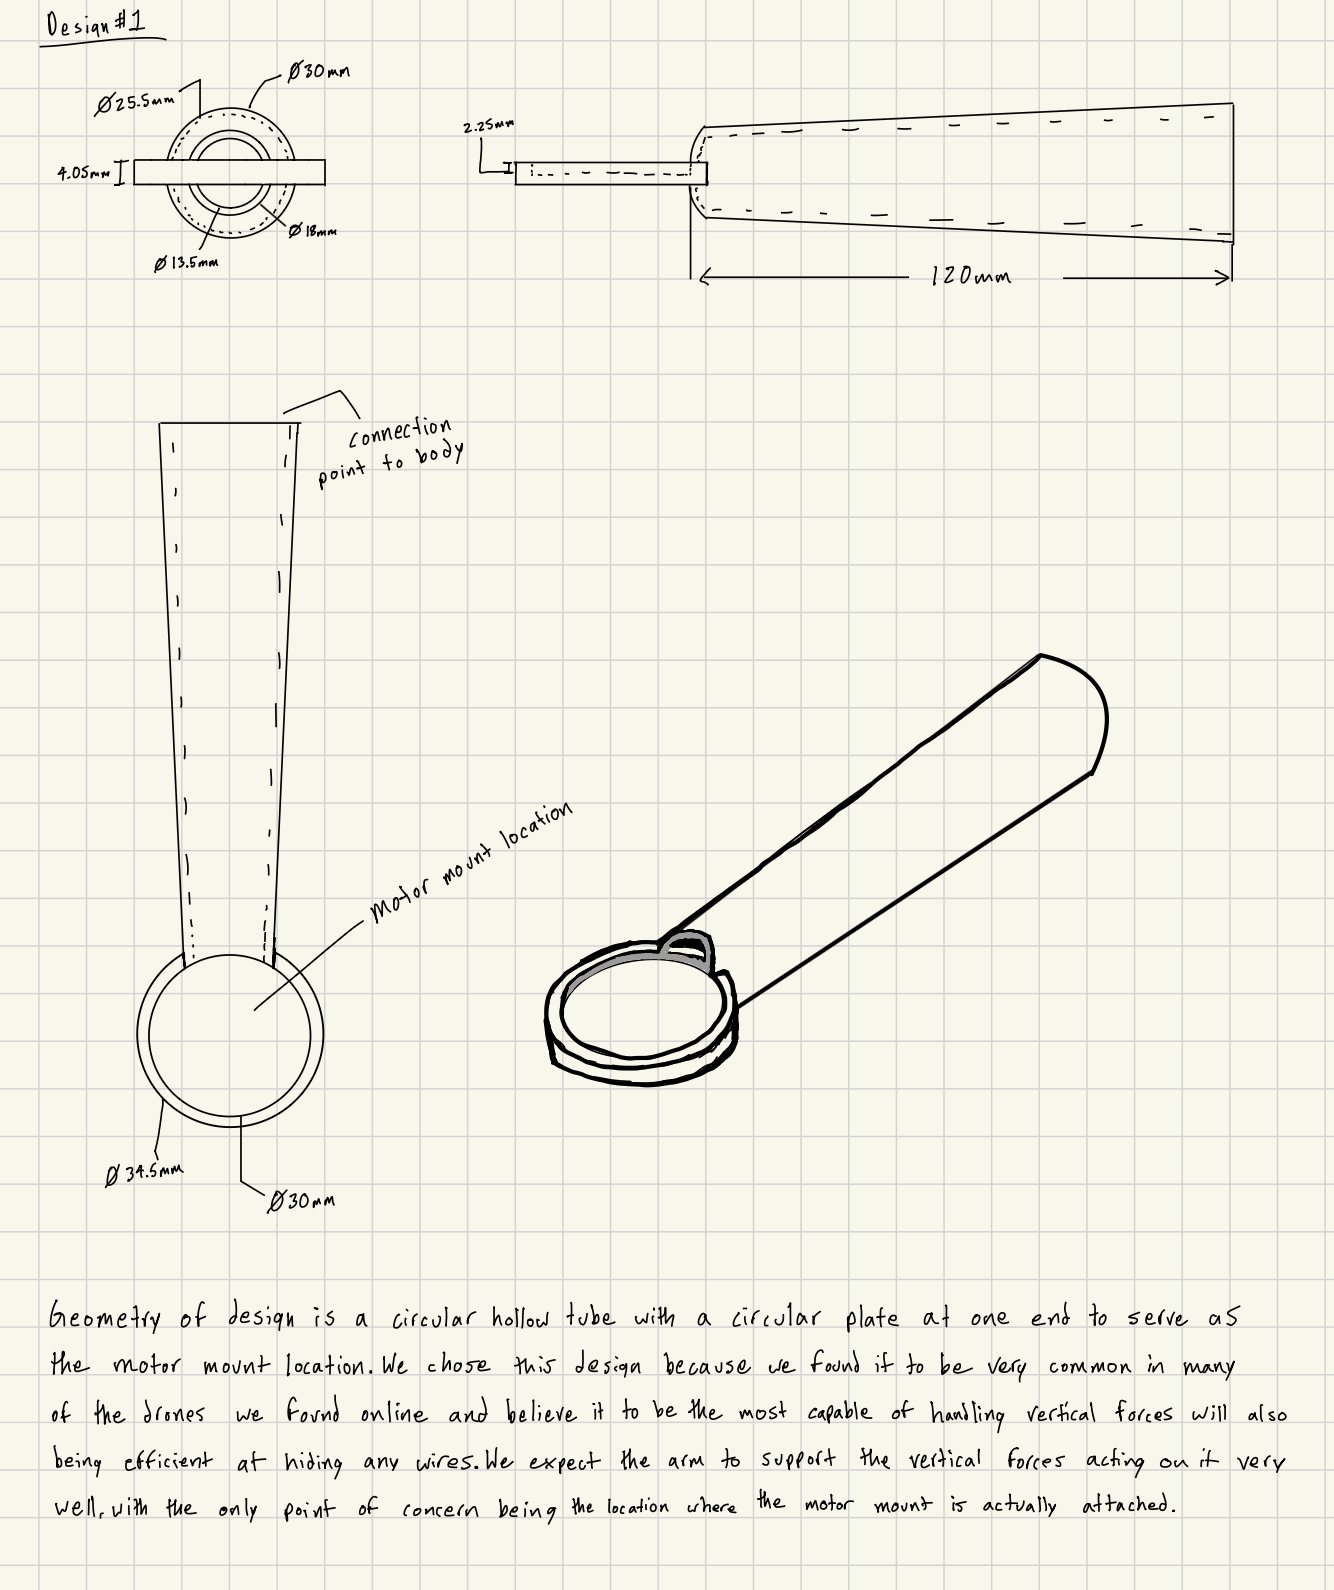

## Task 3: Perform thrust-to-weight analysis across all design and material options

Write a MATLAB function that will perform a thrust-to-weight analysis across all design and material options. This analysis will help you evaluate which drone arm design and which material optimizes payload capacity while meeting suggested safety requirements. 

- Your design must support a minimum payload of 0.5kg. 

- Your design must meet a thrust-to-weight ratio of at least 2:1 to ensure safe and stable flight. This safety standard is widely used in drone design. Conceptually, it means that the drone's maximum thrust must be at least twice its weight. This ensures stable hovering and maneuvering with a safety margin. Note that the thrust-to-weight safety margin is a system-level safety standard for drone flight that is distinct from the structural safety factor of the drone arms (which you will evaluate later through finite element analysis).

- Your goal is calculate maximum payload capacity for each design and material option (i.e. what is the heaviest payload your drone design could carry while still allowing the drone to safely take off?)

Ensure that the results of your analysis can be readily interpreted, e.g. in the form of a summary table or plot.

Note: if you have two drone arm designs, the expected output should be 12 payload capacity estimates (2 designs across 6 materials options).

% total thrust
total_thrust = n_motor * m_thrust; % kg

% Get volume of each arm from CAD file
arm_volume = 2.04e-5; % m^3 

% Create a list to store payload capacity for each design
thrust_weight = zeros(1,n_material);

% Loop over each design and material

for j = 1:n_material

  density = materials(j).rho_kg_m3; % kg/m^3
  arm_weight = arm_volume * density; % kg

  % mass of the entire drone, including the arms 
  base_mass = tot_weight + arm_weight*n_arm; % kg
    
  % Since the target thrust-weight ratio is 2:1, the maximum wegiht for the entire
  % drone is tot_thrust/2. Subtracting base mass gives the maximum payload
  % that doesn't exceed the 2 to 1 ratio condition
  max_payload = total_thrust/2 - base_mass; % kg
  thrust_weight(j) = max_payload;
  fprintf("%s : %.2f\n", materials(j).name, max_payload)
end

Carbon Fiber Composite (CFRP) : 0.87
Aluminum Alloy : 0.78
Fiberglass Composite (GFRP) : 0.84
PLA Plastic : 0.90
ABS Plastic : 0.91
Wood (Birch) : 0.95


## Task 4: Perform finite element analysis across all design and material options

Perform finite element analysis (FEA) across all design and material options to evaluate the structural safety factor of your drone arm design. To simplify the task, you will perform the FEA only on a single drone arm.

Using a CAD software of your choice, first create a 3D model of one drone arm for each of your designs. Be sure your model can be exported as a STEP or STL file for analysis in MATLAB.

- Recommended CAD software options: Tinkercad, Onshape, Fusion 360, Solidworks (most have free versions)

Import your model into MATLAB and perform FEA. In your FEA model, you should model and apply two loads to the drone arm: upward thrust force from the motor and downward weight of the motor.

- Helpful resources: [online tutorial](https://matlabacademy.mathworks.com/details/introduction-to-finite-element-analysis-with-matlab/otmlfea), documentation for [Structural Mechanics](https://www.mathworks.com/help/pde/structural-mechanics.html) and [Partial Differentiation Equation Toolbox](https://www.mathworks.com/help/pde/index.html?s_tid=CRUX_lftnav), and [example workflow](https://www.mathworks.com/help/pde/ug/deflection-analysis-of-bracket-femodel.html)

For each design and material combination, you should report the overall maximum displacement, maximum stress, and factor of safety and include visualizations of the x-, y-, and z-displacement and Von Mises stress. Ensure that your results are presented for easy interpretation (e.g. present a table with numerical results, clearly labeled subplots for the visualizations).

- The factor of safety compares how strong a material is to how much stress it experiences, indicating whether a design is safe under the given loads. For this project use the equation: $\textrm{FoS}=\frac{\textrm{Material}\;\textrm{Yield}\;\textrm{Strength}\;\left(\textrm{Pa}\right)}{\textrm{Maximum}\;\textrm{von}\;\textrm{Mises}\;\textrm{Stress}}$. Yield strength indicates how much stress a given material can withstand before permanently deforming. Maximum von Mises stress (derived from your FEA model) is a measure of how much stress your design experiences under the applied loads.

- A typical engineering safety margin for FoS is ~1.5-2+

- This [example](https://www.mathworks.com/help/pde/ug/deflection-analysis-of-bracket-femodel.html) demonstrates the plots you are asked to include in your results

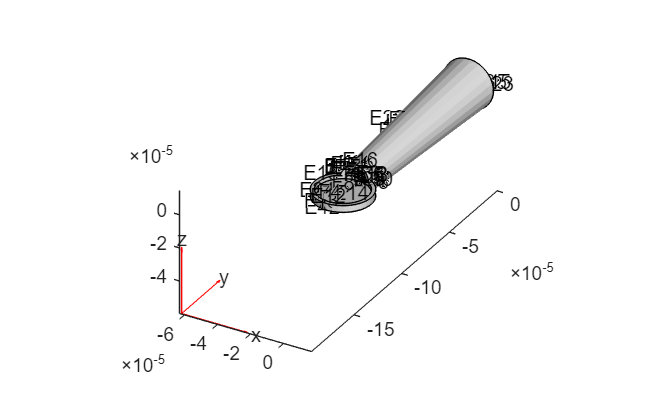

gm = fegeometry("taperedDroneArm.step");
gm = scale(gm, 1e-3); % convert to meters for correct physical units
pdegplot(gm, FaceLabels="on", EdgeLabels="on")


md = femodel(AnalysisType="structuralStatic", Geometry=gm);
% Generate a mesh
md = generateMesh(md);

% Apply boundary conditions (fix base of arm where it would be
% attached to drone body)
fixed_face = 15;
md.FaceBC(fixed_face) = faceBC(Constraint="fixed");
md.CellLoad(:) = cellLoad(Gravity=[0,0,-g]); % m/s^2

% Calculate the net tranction on the motor mount
mount_area = 7.07e-4; % m^2
thrust_force = m_thrust*g; % N
motor_weight = motor*g; % N
net_force = thrust_force - motor_weight; % N
net_traction = net_force /mount_area; % Pa

% Apply the net traction on the face of the motor mount
load_face = 8;
md.FaceLoad(load_face) = faceLoad(SurfaceTraction=[0,0, net_traction]);

% List of factor of safety for each material
FoS_static = zeros(1,n_material);

% Store the solution data for the visualization later
solution = {[],[],[],[],[],[]};
for i = 1:n_material
    % Input the material information selected above
    md.MaterialProperties = materialProperties( ...
        YoungsModulus=materials(i).E_Pa, ...
        PoissonsRatio=materials(i).nu, ...
        MassDensity=materials(i).rho_kg_m3);
        % solve the FEA model
        solution{i} = solve(md);
        FoS_static(i) = materials(i).yieldStrength_Pa/max(solution{i}.VonMisesStress);
end
FoS_static

FoS_static =    67.6545   31.7827   33.3252    7.1313    4.7080    9.4160


## Visualization of the FEA

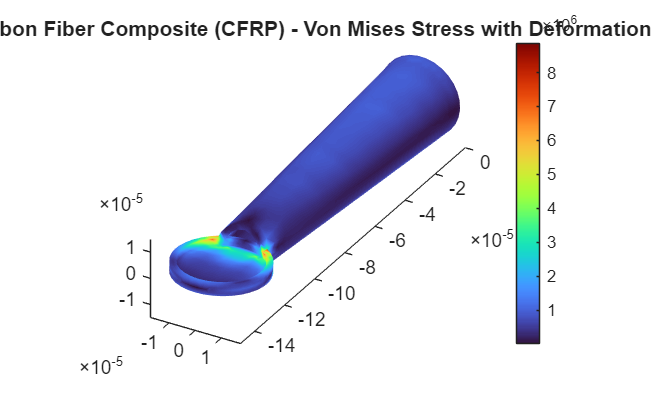

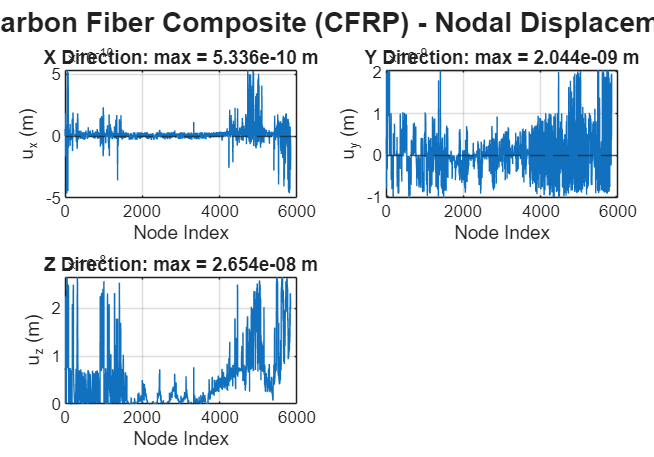

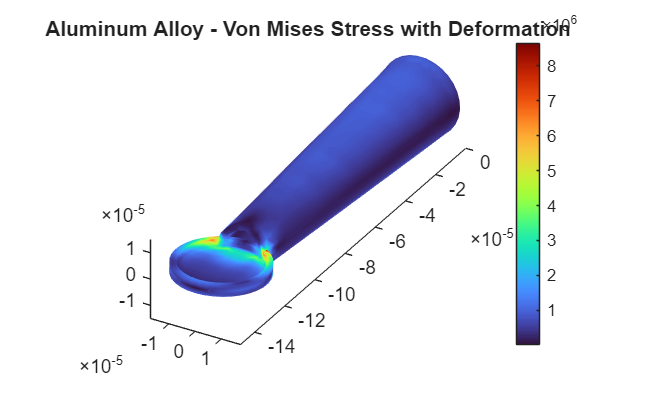

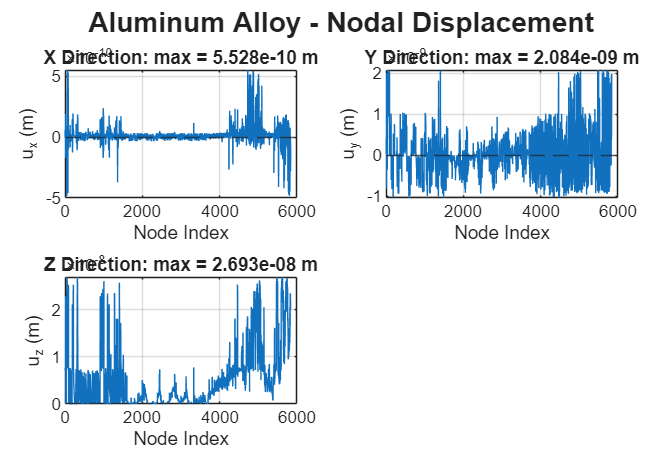

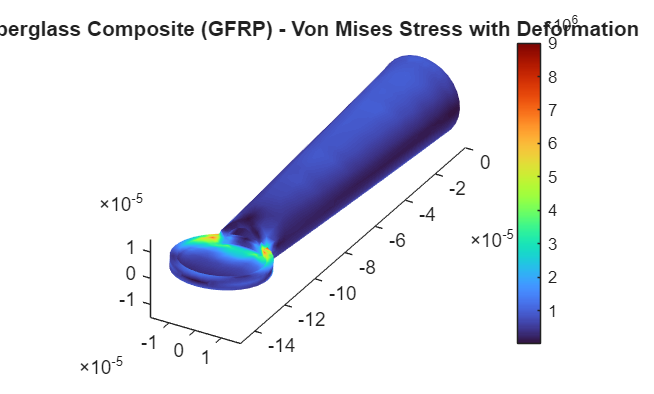

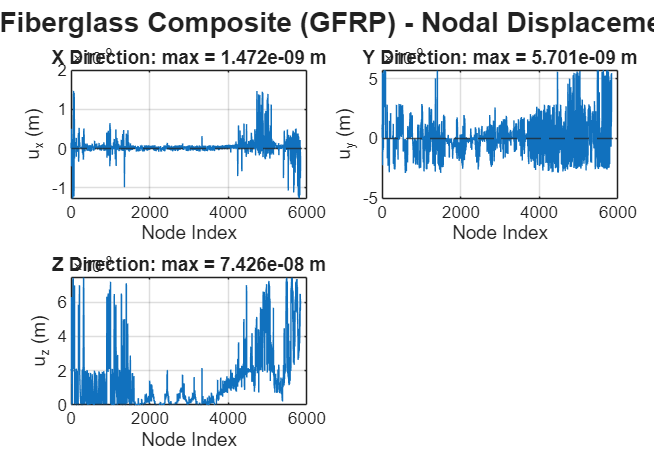

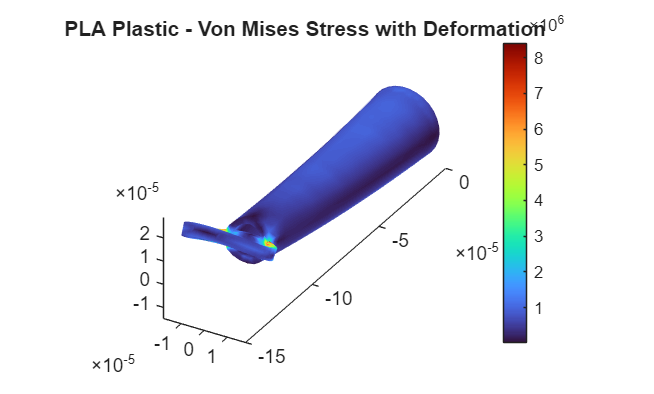

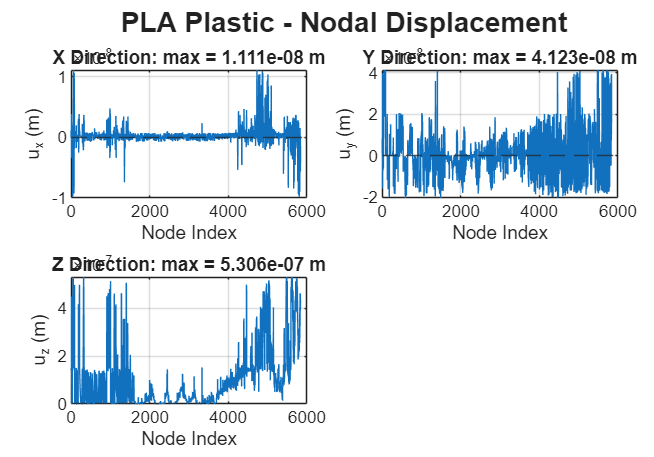

% Loop over the materials and plot the properties above
for i = 1:n_material

    meshData2 = solution{i}.Mesh;
    nodalData2 = solution{i}.VonMisesStress;
    deformationData2 = solution{i}.Displacement;

    displacement_x = solution{i}.Displacement.x;
    displacement_y = solution{i}.Displacement.y;
    displacement_z = solution{i}.Displacement.z;


    % Get material name
    materialName = string(materials(i).name);

    %% Von Mises stress visualization
    stressFigure = figure( ...
        "Name", materialName + " - Von Mises Stress", ...
        "NumberTitle", "off");

    resultViz2 = pdeviz(stressFigure, ...
        meshData2, ...
        nodalData2, ...
        "DeformationData", deformationData2, ...
        "DeformationScaleFactor", 50, ...
        "MeshVisible", "off", ...
        "Title", materialName + ...
        " - Von Mises Stress with Deformation");

    %% Displacement visualization
    displacementFigure = figure( ...
        "Name", materialName + " - Displacement", ...
        "NumberTitle", "off", ...
        "Color", "w", ...
        "Position", [100, 100, 1000, 700]);

    % Create a compact 2-by-2 layout
    layout = tiledlayout(displacementFigure, 2, 2, ...
        "TileSpacing", "compact", ...
        "Padding", "compact");

    title(layout, ...
        materialName + " - Nodal Displacement", ...
        "FontSize", 14, ...
        "FontWeight", "bold");

    %% X displacement
    ax1 = nexttile(layout);

    plot(ax1, displacement_x);
    yline(ax1, 0, "--");

    grid(ax1, "on");
    box(ax1, "on");

    title(ax1, sprintf( ...
        "X Direction: max = %.3e m", ...
        max(abs(displacement_x))));

    xlabel(ax1, "Node Index");
    ylabel(ax1, "u_x (m)");

    %% Y displacement
    ax2 = nexttile(layout);

    plot(ax2, displacement_y);
    yline(ax2, 0, "--");

    grid(ax2, "on");
    box(ax2, "on");

    title(ax2, sprintf( ...
        "Y Direction: max = %.3e m", ...
        max(abs(displacement_y))));

    xlabel(ax2, "Node Index");
    ylabel(ax2, "u_y (m)");

    %% Z displacement
    ax3 = nexttile(layout);

    plot(ax3, displacement_z);
    yline(ax3, 0, "--");

    grid(ax3, "on");
    box(ax3, "on");

    title(ax3, sprintf( ...
        "Z Direction: max = %.3e m", ...
        max(abs(displacement_z))));

    xlabel(ax3, "Node Index");
    ylabel(ax3, "u_z (m)");

end

## Extra Feature: Ground Impact Analysis

Here, we analyze the structural property of drone arm for each material-design combination in case of a free-fall crash to the ground from a certain height. 

The assumption is the following:

- Impact is idealized as a static load

- Force is defined as a time-average of the force during the collision to the ground, given as


$$F=m*\frac{v_i }{t_i },\textrm{where}\;v_i \;\textrm{and}\;t_i \;\textrm{are}\;\textrm{speed}\;\textrm{right}\;\textrm{before}\;\textrm{the}\;\textrm{collision},\textrm{and}\;\textrm{duration}\;\textrm{of}\;\textrm{the}\;\textrm{collision}\;\textrm{respectively}$$


- Use dynamic load factor of 2 for a sudden load

- Force is distributed equally over the mount surface

% Analyze the structural property of drone arm for each 
% material in case of a free-fall crash to the ground from 
% a certain height. We assume that the impact can be idealized
% as an static load as following: force is a time average given 
% as mass*v/t_impact, where v is the speed of the drone right
% before the contact with the ground, and t_impact is the duration
% of the impact. Since we would like to consider the dynamic effect
% on the arm, we amplified the force by dynamic load factor of 2 for
% a sudden applied load. We assume that the force is applied on the
% motor mount.
% We use the same FEA model as above

% Parameter for crash situation
h_drop = 1.0; % m,  height of the drone free-fall
t_impact = 0.01; % s,  duration of the impact
DLF = 2; % dynamic load factor for a suddenly applied load
v_impact = sqrt(2*g*h_drop); % m/s,  obtained by solving the conservation of energy equation


% List of Fos
FoS_dynamic =  zeros(1,n_material);

% Calculation for FoS for each material
for j = 1:n_material
    mat = materials(j);

    % Total drone mass
    arm_mass = arm_volume * mat.rho_kg_m3; % kg
    impact_mass = tot_weight + n_arm*arm_mass; % kg

    % Impulse-momentum average impact force, amplified by the dynamic load factor
    F_avg = impact_mass * v_impact / t_impact; % N
    % Multiply by dynamic load factor
    F_dynamic = DLF * F_avg; % N
    traction_design = F_dynamic / (4*mount_area); % Pa

    md.MaterialProperties = materialProperties( ...
        YoungsModulus=mat.E_Pa, ...
        PoissonsRatio=mat.nu, ...
        MassDensity=mat.rho_kg_m3);
    md.FaceLoad(load_face) = faceLoad(SurfaceTraction=[0,0,traction_design]);

    solution = solve(md);

    % Calculate the factor of safety
    FoS_dynamic(j) = mat.yieldStrength_Pa / max(solution.VonMisesStress);

end

## Extra Feature: Cost Calculation

Here, we calculate the cost for each material-design combination. We got the cost USD/kg for each material from the internet. 

% Using values for the cost of material in USD/kg
% Price values were searched up on the internet

costs= [200;15;40;30;30;10]; % USD/kg

% DESIGN1
for i = 1:6 
    % Add cost USD/kg to the material structure
    materials(i).cost_USD_per_kg = costs(i);
    % Calculates the mass in kg by multiplying density times volume 
    materials(i).mass_kg = materials(i).rho_kg_m3*arm_volume*4;
    % Rounds total cost to 2 significant figures
    materials(i).total_cost_USD = round(materials(i).mass_kg.*materials(i).cost_USD_per_kg,2,'significant');  
end 

% Converts data in struct to a table
materialsBudgetTable = struct2table(materials); 
budgetTable = materialsBudgetTable(:, {'name' , 'mass_kg', 'cost_USD_per_kg', 'total_cost_USD'})

budgetTable = 6×4 table
                 name                  mass_kg    cost_USD_per_kg    total_cost_USD
    _______________________________    _______    _______________    ______________

    "Carbon Fiber Composite (CFRP)"    0.13056          200                 26     
    "Aluminum Alloy"                   0.22032           15                3.3     
    "Fiberglass Composite (GFRP)"      0.15504           40                6.2     
    "PLA Plastic"                        0.102           30                3.1     
    "ABS Plastic"                      0.08568           30                2.6     
    "Wood (Birch)"                     0.04896           10               0.49     


## Numerical Data Analysis

Here, we calculate the score for each material, based on the four factors calculated above: maximum payload, static factor of safety, dynamic factor of safety and cost. 

We use weighted scoring method to consider all the four factors. As for the weight for each factor, it depends on the purpose of drone: education, racing, monitoring, delivering etc. Here, our focus is payload capacity and the safety of the drone. For this purpose, we naturally assign high weight for the payload factor, and two factor of safety  However, As a result of the analysis, we found that the static FoS for all the materials are far more than 2.0, which is the standard for safety. Therefore, the value of static FoS does not work as a differentiating factor. Therefore, we assigIn only small value to static FoS, and assign large weights for payload capacity and dynamic FoS.

The following explains the scoring method for each factor. We limit the score for each factor between 0 and 1, and calculated the weighed sum to get the overall score.

The following is the weight distribution we decided:

Static FoS: 10%, Dynamic FoS:35%, Cost: 20%, Payload capacity: 35%

Payload Capacity: Use 


$$\textrm{score}=\min \left(\frac{\left(x-x_{\textrm{acceptable}} \right)}{x_{\max } -x_{\textrm{acceptable}} },0\right),\textrm{where}\;x_{\textrm{acceptable}} =0\ldotp 5$$


Since the minimum acceptabe value for payload capacity is 0.5kg, we assign 0 if the material has the value less than 0.5.

Static/Dynamic FoS:


$$\textrm{score}=\min \left(1,\frac{x}{x_{\textrm{safety}} }\right),\textrm{where}\;x_{\textrm{safety}} =1\ldotp 5,\textrm{which}\;\textrm{is}\;\textrm{the}\;\textrm{standard}\;\textrm{for}\;\textrm{safety}$$


We assign 1 for any material that has more than 1.5 FoS, and punish severly for material that has less than 1.5

Cost:


$$\textrm{score}=\min \left(1,\frac{x_{\textrm{acceptable}} }{x}\right),\textrm{where}\;x_{\textrm{acceptable}} =5\;\textrm{and}\;x=\textrm{cost}\;\textrm{for}\;\textrm{the}\;\textrm{arm}\;\textrm{for}\;\textrm{the}\;\textrm{material}$$


We assign maximum score for any material that cost less than 5$, and punish materials that cost more than 5$

% Implement the scailing and scoring
% We have four factors to determine the best material for each design.
% Each factor is scaled on a 0-1 score, then combined into a weighted
% overall score.

% WEIGHT (Max Payload) - higher is better, minimum of 0.5kg
max_payload = max(thrust_weight);
min_payload = 0.5; % kg
a = thrust_weight;
weightScore = zeros(1, n_material);
for i = 1:n_material
    if a(i) < min_payload
        weightScore(i) = 0;
    else
        weightScore(i) = (a(i) - min_payload)/(max_payload - min_payload);
    end
end

% FoS STATIC - higher is better
a = FoS_static;
% Safety factor for both static and dynamic FoS
safety_factor = 1.5;
staticScore = zeros(1, n_material);
for i = 1:n_material
    if a(i) > safety_factor
        staticScore(i) = 1;
    else
        staticScore(i) = (a(i)/safety_factor)^2
    end
end

% FoS DYNAMIC - higher is better
a = FoS_dynamic;
dynamicScore = zeros(1, n_material);
for i = 1:n_material
    if a(i) > safety_factor
        dynamicScore(i) = 1;
    else
        dynamicScore(i) = (a(i)/safety_factor)^2;
    end
end
% BUDGET - lower is better
minBudget= min(budgetTable.total_cost_USD);
a = budgetTable.total_cost_USD;
cost_acceptable = 5; % $
costScore = zeros(1, n_material);
for i = 1:n_material
    if cost_acceptable < a(i)
        costScore(i) = cost_acceptable / a(i);
    else
        costScore(i) = 1;
    end
end

% Combine scores into a weighted overall score
% Weight distribution: Static 10%, Dynamic 35%, Weight 35%, Cost 20%
overallScore = (0.10.*staticScore')+(0.35.*dynamicScore')+(0.35.*weightScore')+(0.20*costScore');

% Build and sort the trade study summary table in descending order
tradeStudyTable = table(budgetTable.name, weightScore', staticScore', dynamicScore', costScore', overallScore, ...
    'VariableNames', {'Name', 'Weight Score', 'Static Score', 'Dynamic Score', 'Cost Score', 'Overall Score'});
tradeStudyTable = sortrows(tradeStudyTable,"Overall Score","descend")

tradeStudyTable = 6×6 table
                 Name                  Weight Score    Static Score    Dynamic Score    Cost Score    Overall Score
    _______________________________    ____________    ____________    _____________    __________    _____________

    "Carbon Fiber Composite (CFRP)"      0.81908            1                   1        0.19231         0.77514   
    "Fiberglass Composite (GFRP)"        0.76481            1             0.63458        0.80645         0.75108   
    "Aluminum Alloy"                     0.62008            1             0.51709              1         0.69801   
    "Wood (Birch)"                             1            1            0.061426              1          0.6715   
    "ABS Plastic"                        0.91859            1          


best_material = materials(1);

best_material = struct with fields:
                name: "Fiberglass Composite (GFRP)"
           rho_kg_m3: 1900
                E_Pa: 2.5000e+10
                  nu: 0.2800
    yieldStrength_Pa: 300000000
      cost_USD_per_m: 15
     cost_USD_per_kg: 40
             mass_kg: 0.1550
      total_cost_USD: 6.2000


## Extra Frature: Frequency Analysis

% Here, we analyze the frequency property of the drone arm. We assume that
% the rotation frequency is calculated by f=RPM/60. We use Matlab
% structuralFrequency analysis mode to get the value of displacement and
% Von Mises Stress for each excitation frequency

% For the RPM, we first calculate the RPM range the drone takes, using the
% formula from a paper

% Calculate the thrust for hovering, including the weight of a camera
% Define the thrust for hovering as the thrust range of 1-1.2 times the
% entire weight

% Assume the weight of the camera is 0.1kg
camera_weight = 0.1; % kg

% Total weight
arm_weight = arm_volume*best_material.rho_kg_m3

arm_weight = 0.0388

weight_with_camera = tot_weight + n_arm*arm_weight + camera_weight % kg

weight_with_camera = 1.2550



% Calculate the rpm in thousands of the propeller required for the thrust range, based
% on the formula

 
$$\begin{array}{l}
T=\left(2*\pi *R^2 *\rho *{\left(\textrm{propeller}\;\textrm{constant}*{\left({\textrm{rpm}}^{\textrm{power}\;\textrm{factor}} \right)} \right)}^2 \right){\;}^{\frac{1}{3}} ,\textrm{where}\;R=0\ldotp 127m,\textrm{rho}=1\ldotp 225\frac{\textrm{kg}}{m^3 },\\
\textrm{propeller}\;\textrm{constant}=0\ldotp 048,\;\textrm{power}\;\textrm{factor}=3\ldotp 55
\end{array}$$


    By rearrange the equation for rpm, and notate propeller constant and power factor as pc and pf respectively,


$$\textrm{rpm}={\left(\frac{1}{\textrm{pc}}\sqrt{\frac{T^3 }{2\pi R^2 \rho }}\right)}^{\frac{1}{\textrm{pf}}}$$


% Now, we obtain the rpm in thousands from the formula
pc = 0.048;
pf = 3.55;
R = 0.127; % m
rho = 1.225; % kg/m^3

% Determin the range of RPM, where upper limit us determined by the maximum
% thrust force and the lower limit is defined as the 80% of the weight of
% the entire drone

% Lower limit
RPM_range(1) = (1/pc*(((weight_with_camera*0.8*g/n_prop).^3)/(2*pi*R^2*rho)).^0.5).^(1/pf);
% Upper limit
RPM_range(2) = (1/pc*((m_thrust*g.^3)/(2*pi*R^2*rho)).^0.5).^(1/pf);

RPM = RPM_range*1000; % rev/min



% Since we use the same geometry, the setup for this analysis is almost
% identcal to that of the static FoS analysis above.

% Create a new model for structural Frequency
response_md = femodel(AnalysisType="structuralFrequency", Geometry=gm);
% Generate mesh
response_md = generateMesh(response_md);

% Add boundary condition
response_md.FaceBC(fixed_face) = faceBC(Constraint="fixed");

response_md =   1×1 femodel array

Properties for analysis type: structuralFrequency

            AnalysisType: "structuralFrequency"
                Geometry: [1×1 fegeometry]
      MaterialProperties: [0×1 materialProperties]

   Boundary Conditions
                  FaceBC: [1×15 faceBC]
                  EdgeBC: [0×43 edgeBC]
                VertexBC: [0×28 vertexBC]

   Loads
                CellLoad: [0×1 cellLoad]
                FaceLoad: [0×15 faceLoad]
                EdgeLoad: [0×43 edgeLoad]
              VertexLoad: [0×28 vertexLoad]

   Other Parameters
            DampingAlpha: 0
             DampingBeta: 0
    ReferenceTemperature: []
           SolverOptions: [1×1 pde.PDESolverOptions]

  Show all properties


% Apply the material condition
response_md.MaterialProperties = materialProperties( ...
    YoungsModulus=materials(2).E_Pa, ...
    PoissonsRatio=materials(2).nu, ...
    MassDensity=materials(2).rho_kg_m3);


% For Excitation frequency, we consider rotation frequency and
% blade passing frequency. We compute the range for both below
% We consider the safety margin of 20% for both lwer and upper limit of excitaition frequency range
% We assume three bladed propeller
n_blade = 3;
margin = 0.2;

% Rotaiton frequency
rot_freq = RPM/60; % Hz
% Blade passing freqeuncy
blade_freq = n_blade*rot_freq; % Hz
% Add the margin
rot_freq_margin = [rot_freq(1)*(1-margin), rot_freq(2)*(1+margin)];
blade_freq_margin = [blade_freq(1)*(1-margin), blade_freq(2)*(1+margin)];
% convert the frequencies to angular frequency
rot_freq_margin_ang = rot_freq_margin*2*pi;
blade_freq_margin_ang = blade_freq_margin*2*pi;


% Number of samples of excitation frequency
n_excitation = 100;
% Get excitation frequency for frequency analysis
rotation = linspace(rot_freq_margin(1), rot_freq_margin(2), n_excitation);
blade = linspace(blade_freq_margin(1), blade_freq_margin(2), n_excitation);

excitation_freq = unique([rotation, blade]);
excitation_omega = 2*pi*excitation_freq;

% Assume damping ratio of 0.02
damping_ratio = 0.02;

% Get traction on the motor mount
traction = [0, 0, net_traction]; % Pa

% Apply force to the frequency model
response_md.FaceLoad(load_face) = faceLoad(SurfaceTraction=traction);
% Solve the frequency model
sol_response = solve(response_md, excitation_omega,...
    DampingZeta=damping_ratio);

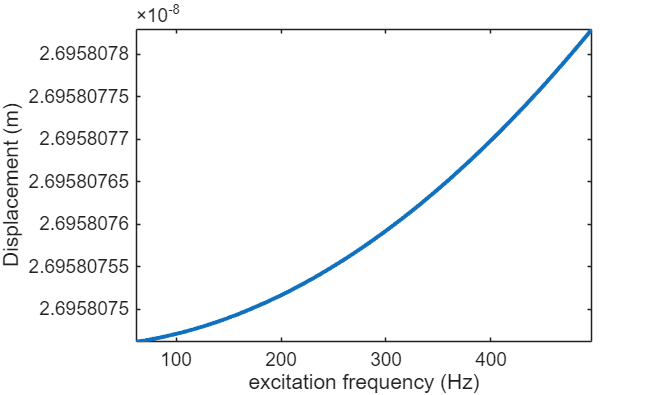

% Analyze the frequency model solution
% In this section, we get three largest values for the displacement
% magnitude and Von Misses stress amplitude respectively, including the
% values close to the peaks to indicate at which excitation frequency the
% drone is under more displacement or stress.

% Get maximum displacement of all nodes at each frequency.
% Also get the number of the mesh node that has the maximum displacement at
% each frequency
disp_abs= abs(sol_response.Displacement.Magnitude);
[max_disp_each_freq, index] = max(disp_abs, [], 1);

% Get maximum Von Misses stress of all nodes at each frequency
% As above, get the correspojnding node number too
von_mises_abs = abs(evaluateVonMisesStress(sol_response));
max_von_mises_each_freq = max(von_mises_abs, [], 1);

figure
plot(excitation_freq, max_disp_each_freq, LineWidth=2), xlabel("excitation frequency (Hz)"), ylabel("Displacement (m)"),...
    title("Displacement"), axis tight

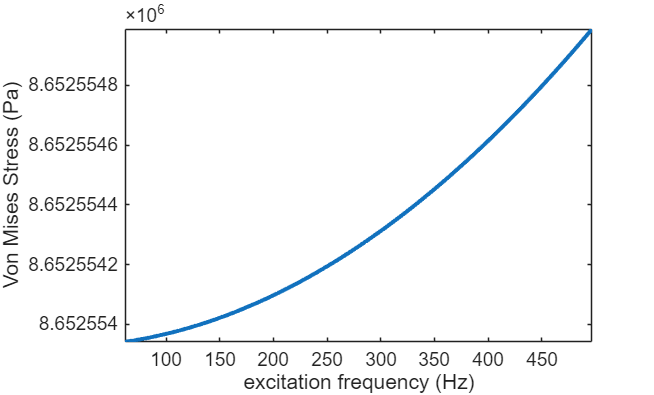

figure
plot(excitation_freq, max_von_mises_each_freq, LineWidth=2), xlabel("excitation frequency (Hz)"), ylabel("Von Mises Stress (Pa)"),...
    title("Displacement"), axis tight

## Interpretation of Results - Final Recommended Design Solution

Using the results of your thrust-to-weight analysis and finite element analysis, recommend a final drone arm design that meets all required constraints. Your recommendation should clearly identify the selected design (arm geometry and material choice), make use of quantitative results to justify your decisions, demonstrate that the design meets the constraints, explain the trade-offs considered, and include comparisons to alternative designs.

As a result of our analys, we recommend carbon fiber or fiberglass composite as a material for this hollow tapered arm design.

Both of the material-design combination satisfies a constraint of minimum payload capacity of 0.5kg. For both carbon fiber and fiberglass, the payload capacity is satisfactory, 0.8191 and 0.7648kg respectively. Other material such as wood, ABS and PLA also have high, for some of them higher, payload capacity. In this analysis method, what distinguishes the two is that they maintain high structural integrity, while not compromizing the payload capacity. Aluminum alloy has high structural integrity, but its payload capacity is not as high as carbon fiber and fiber glass. As for wood, ABS and PLA, its structural integrity is insufficient. Whether you choose carbon fiber or glass fiber depends on your budget. If sufficient budget is available and the drone requires highest integrity, carbonfiber would be the best choice. If not, fiberglass would still be a good option.

What are some limitations of your work?

First, we have a lot of missing parts that can affect the performance of the drone, such as body, motor, propeller, bolts, etc. We think that these missing parts would give more concrete and realistic arm profile, which lead to more accurate boundary conditions. The actual shape of attachment face to the body, more accurate load distribution over mount surface, vulnerability at the joints, etc. With these conditions considered, the estimation of the possible payload capacity would be more accurate.

Second, there are several factors that should be considered such as aerodynamic effect and thermal property. Since we only considered the static structural property of the drone, we don't know how the drone would behave under the condition with wind or rain. Also, we don't know how high temperature affect the electric components or the frame itself. There are many parameters that should be considered for the overall performance estimation, such as battery life and motor Kv specification. With these specific conditions included, we will be able to get more reliable results.

Third, the assumption made for frequency analysis still has to be validated. We used the formula from a paper by  C. Huang Shen et. al to calculate the RPM range for the drone, based on the maximum thrust and 80% of the total weight. We used the same parameter values for the propeller constant and power factor. However, the values used for these parameters vary depending on specific components you use. For example, propeller constant depends on propeller diameter and pitch. Therefore, users will have to adjust the parameter values for their specific components. 

What are practical next steps?

We think that the next practical step would be to try to consider more factors that affect the performance, as discussed above. Also, it is important to add more concrete specification for the drone components and CAD for the accuracy of the simulation. If possible, making an actual drone and obtain experimental data to compare with the simulated result would be a very good way to improve the simulation quality too.